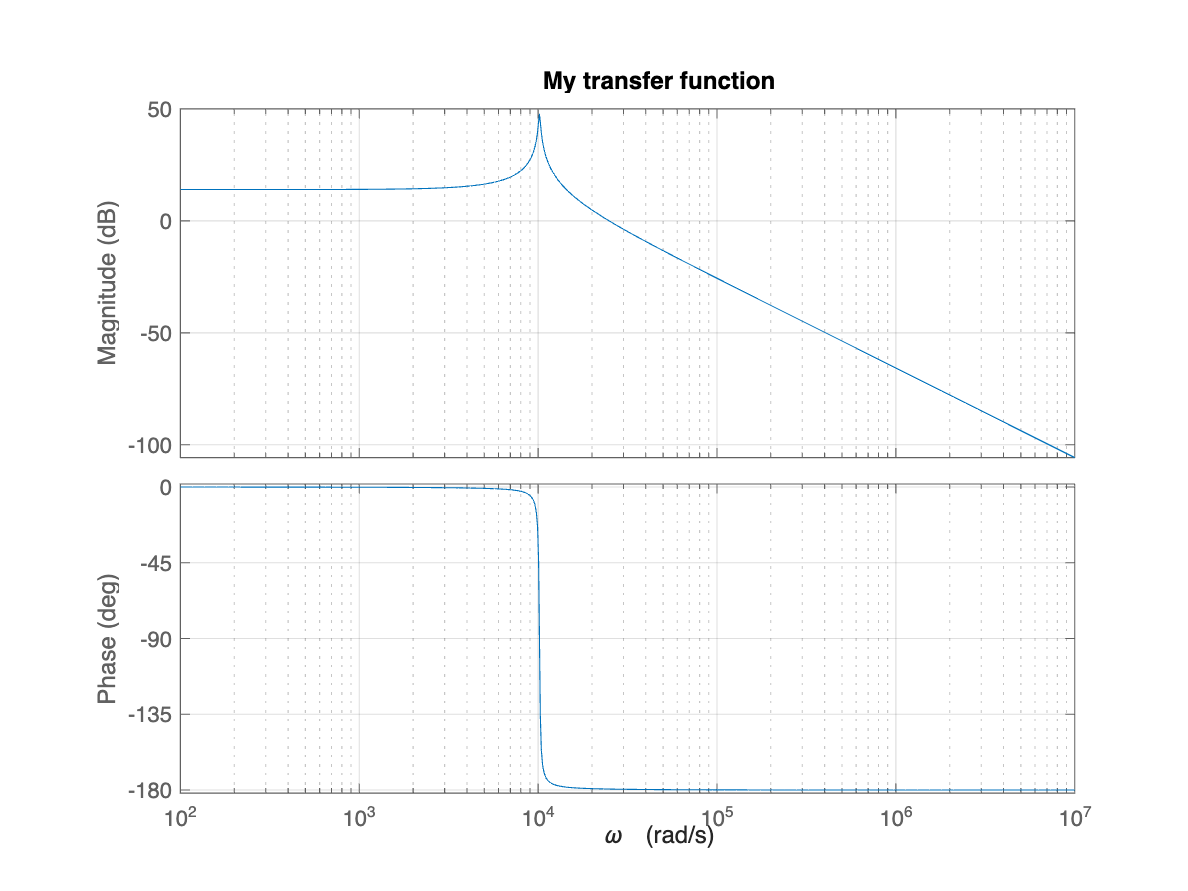

% Script to plot a transfer function
% Preliminary: Clear all variables, clear command window, close all figures

close all;
clear;
clc;

% Create a special variable s that you can use in the following transfer
% function. Alternatively you could just use g = tf(numerator,
% denominator).
s = tf('s');

% Create the transfer function. Assigning variables with the specific values
% makes it much more readable. You could also let matlab calculate w0 and Q
% form L, C, and R if you want an even more elegant solution.

Vin = 5;
L = 42e-6;
C = 230e-6;
R = 20;             %wir benutzen 20 ohm, da 4ohm zu klein(pmos wird zu heiß)
w0 = 1/sqrt(L*C);   % Resonance Frequency
Q = R*sqrt(C/L);   % Quality factor
D = 1/(2*Q);       % Dämpfungsgrad

G = tf(Vin, [1/(w0^2), 1/(w0*Q), 1]);

% Plot the transfer function from 1e2 rad/s to 1e7 rad/s (for omega)
figure;
bode(G, {1e2, 1e7});
grid on;
title('My transfer function');
xlabel("\omega");

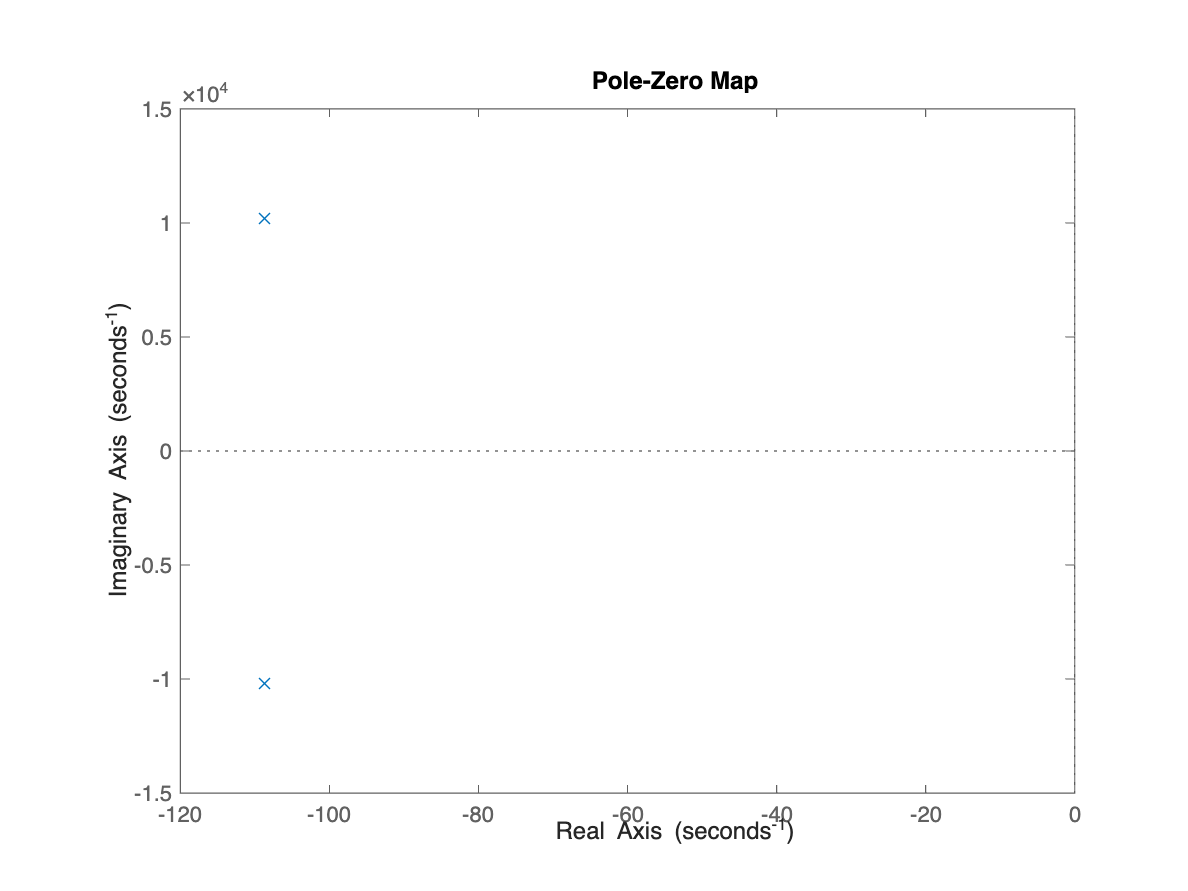


% Plot the Pole-zero-Map
figure;
pzmap(G);

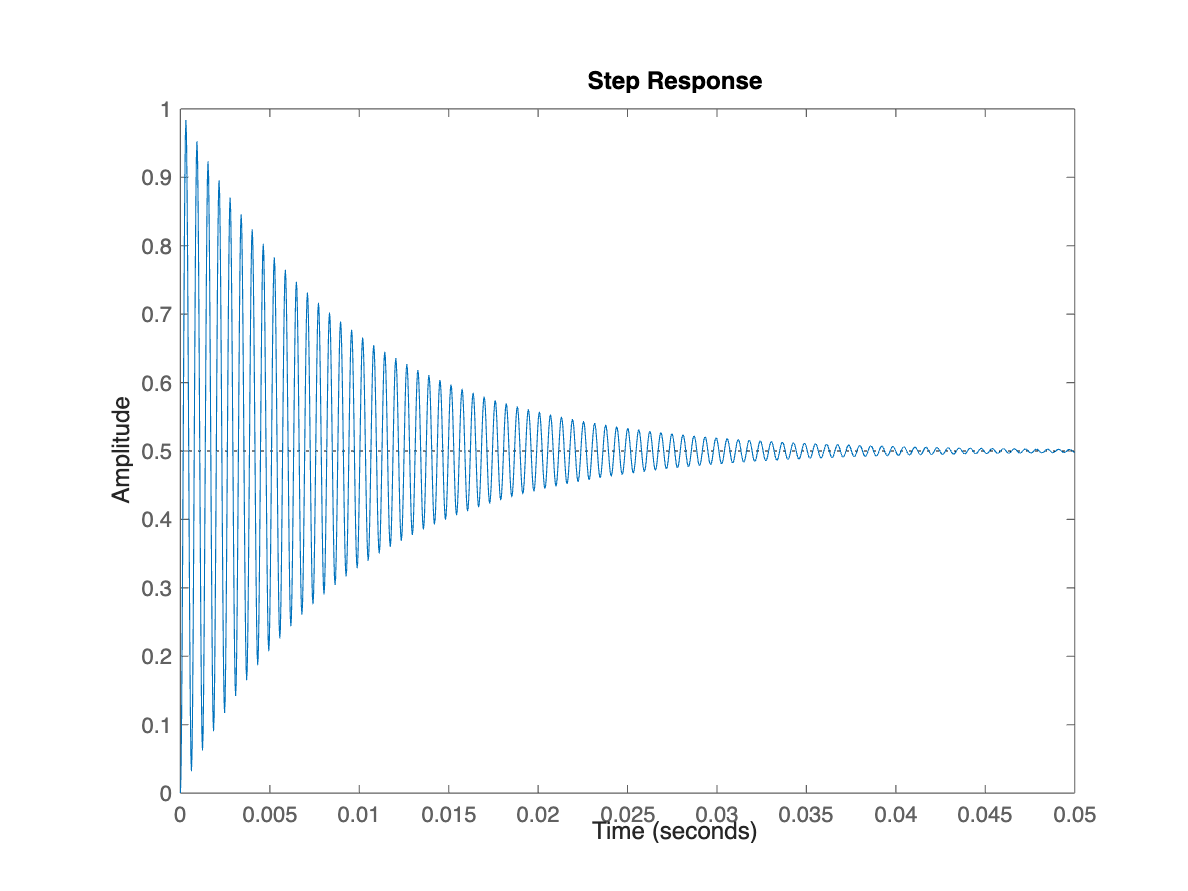


% Show step response with dutycycle of 10%
step(0.1*G);